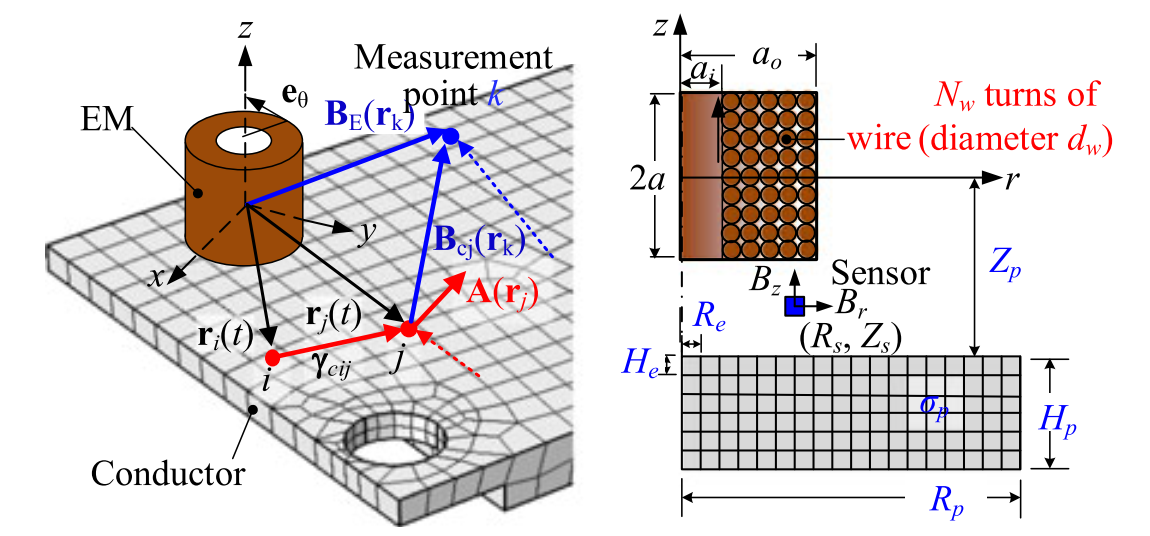

## Governing Equation

123

## Boundary Condition 

123                          

### Outputs

(n = Model.num_elms,  m = number of boundary faces)

**GE.S**                    n-by-n matrix

**GE.Gamma_C **    n-by-n matrix

**GE.V**                    n-by-n matrix

**GE.Gamma_Ex**   n-by-1 matrix

**GE.Gamma_Ey**   n-by-1 matrix

**GE.Gamma_Ez**   n-by-1 matrix

**GE.Q_c**                n-by-3n matrix

**GE.Q_b**                m-by-3n matrix

function GE = BuildGoveringEquation(EM, Model)

mu_0 = 4*pi*1e-7; % (H/m)

GE.S = mu_0 * diag(Model.conductivity);
GE.V = diag(Model.elms_volume);
GE.Gamma_C = Gamma_C_func(Model);
[GE.Gamma_Ex, GE.Gamma_Ey, GE.Gamma_Ez] = Gamma_E_func(Model, EM);

GE.Q_c = Q_c_func(Model);
GE.Q_b = Q_b_func(Model);

end

function Gamma_C = Gamma_C_func(Model)
    
n = Model.num_elms;
r_b = (3/(4*pi) * Model.elms_volume) .^ (1/3);

Gamma_C = zeros(n,n);
% off diagonal entries
for i = 1:n
    for j = i+1:n
        Gamma_C(i,j) = 1 / norm(Model.elms_center(:,j) - Model.elms_center(:,i));
    end
end
Gamma_C = Gamma_C + Gamma_C';
% diagonal entries
for i = 1:n
    Gamma_C(i,i) = 1.5 / r_b(:,i);
end
Gamma_C = Gamma_C / (4*pi);

end

function [Gamma_Ex, Gamma_Ey, Gamma_Ez] = Gamma_E_func(Model, EM)

Gamma_Ex = zeros(Model.num_elms, 1);
Gamma_Ey = zeros(Model.num_elms, 1);
Gamma_Ez = zeros(Model.num_elms, 1);

for k = 1:EM.num
    H_w2l = EM.H_w2l(:,:,k);
    R_l2w = EM.R_l2w(:,:,k);
    ai = EM.ai(:,k);
    ao = EM.ao(:,k);
    l = EM.l(:,k);

    elms_center_w = Model.elms_center;
    [elms_center_l_x, elms_center_l_y, elms_center_l_z] = HomogenousTransform(H_w2l, elms_center_w(1,:), elms_center_w(2,:), elms_center_w(3,:));
    elms_center_l = [elms_center_l_x; elms_center_l_y; elms_center_l_z]; % 3-by-num_elms matrix

    Gamma_E_l_x = zeros(1, Model.num_elms);
    Gamma_E_l_y = zeros(1, Model.num_elms);
    Gamma_E_l_z = zeros(1, Model.num_elms);
    for i = 1:Model.num_elms
        elm_center_l = elms_center_l(:,i);

        Gamma_E_l_x(:,i) = integral3( ...
            @(r,z,theta)Gamma_E_integrand(r,z,theta,elm_center_l) .* -sin(theta), ...
            ai,ao,   -l/2,l/2,   0,2*pi                                              );

        Gamma_E_l_y(:,i) = integral3( ...
            @(r,z,theta)Gamma_E_integrand(r,z,theta,elm_center_l) .*  cos(theta), ...
            ai,ao,   -l/2,l/2,   0,2*pi                                              );
    end

    [Gamma_E_w_x, Gamma_E_w_y, Gamma_E_w_z] = HomogenousTransform(R_l2w, Gamma_E_l_x, Gamma_E_l_y, Gamma_E_l_z);

    Gamma_Ex = Gamma_Ex + Gamma_E_w_x';
    Gamma_Ey = Gamma_Ey + Gamma_E_w_y';
    Gamma_Ez = Gamma_Ez + Gamma_E_w_z';
end

end

function value = Gamma_E_integrand(r, z, theta, elm_center)
dx = elm_center(1) - r .* cos(theta);
dy = elm_center(2) - r .* sin(theta);
dz = elm_center(3) - z;
value = sqrt(dx.^2 + dy.^2 + dz.^2) .* r / (4*pi);
end

function Q_c = Q_c_func(Model)
    
n = Model.num_elms;
Q_c = zeros(n, 3*n);

for i = 1:n
    normal = Model.faces_normal(:, Model.elm2face(:,i)); % 3-by-6
    area = Model.faces_area(:, Model.elm2face(:,i)); % 1-by-6
    normal_sign = Model.elm2face_sign(:,i); % 6-by-1
    area_normal = normal .* normal_sign' .* area; % 3-by-6

    Q_c = SetCoefficient(Q_c, i, i, area_normal(:,1)+area_normal(:,3)+area_normal(:,5));

    for dir = [2,4,6]
        next_elm = NextElement(Model, i, dir);
        if next_elm ~= 0
            Q_c = SetCoefficient(Q_c, i, next_elm, area_normal(:,dir));
        end
    end
end

end

function Q_c = SetCoefficient(Q_c, row, k, coef)
n = size(Q_c, 2) / 3;
Q_c(row, n*0+k) = coef(1);
Q_c(row, n*1+k) = coef(2);
Q_c(row, n*2+k) = coef(3);
end

function next_elm = NextElement(Model, current_elm, dir)
face = Model.elm2face(dir,current_elm);
next_elm_candidates = Model.face2elm(:,face)'; % 1-by-2 matrix
next_elm = 0;
for next_elm_candidate = next_elm_candidates
    if next_elm_candidate ~= current_elm
        next_elm = next_elm_candidate;
    end
end
end

function Q_b = Q_b_func(Model)

num_boundary_faces = sum(Model.faces_is_boundary_mask);
Q_b = zeros(num_boundary_faces, 3*Model.num_elms);

boundary_faces_idx = find(Model.faces_is_boundary_mask);
for i = 1:num_boundary_faces
    face = boundary_faces_idx(i);
    normal = Model.faces_normal(:,face);
    elm = Model.face2elm(1,face);
    Q_b = SetCoefficient(Q_b, i, elm, normal);
end

end